load store\Features.mat
feats = feats(feats.Dataset == 2, :);

[X, ev, explvar, npca, names, featsno, eigvec] = POI.PrepareDataMatrixPCA(feats, 0.95);
d1 = 7;
d2 = 10;

plot(ev)

plot(explvar)

net = selforgmap([d1, d2]);

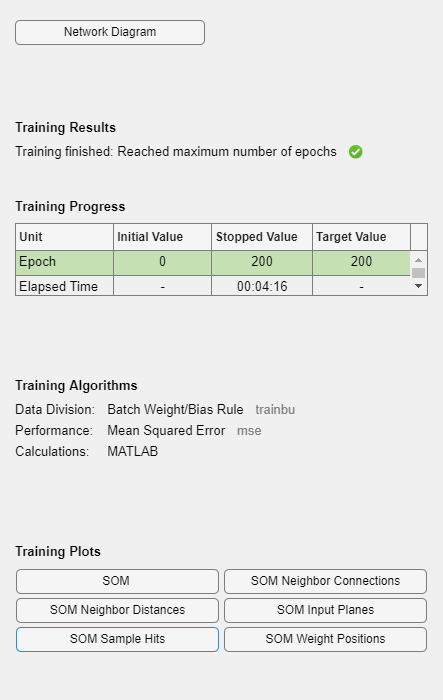

net = train(net,X');

y = net(X');
classes = vec2ind(y);
featsno.Cluster = classes';

POI.sampleClusters(featsno, d1*d2);

save store\Features.mat feats
save store\SOM.mat net